# Monte Carlo methods for sampling

**Note**: This tutorial is mainly based in [Justin Bois](http://bois.caltech.edu) lectures on MCMC as well as the late [David Mackay](https://en.wikipedia.org/wiki/David_J._C._MacKay)'s amazing book *Information Theory, Inference, and Learning Algorithms* that you can legally download [here](http://www.inference.org.uk/mackay/itila/book.html) for free.

So far we have worked with a simple 1D posterior distribution that we could evaluate over a grid of points. That is not always the case. For problems both in statistical physics and statistical modeling we don't always have the luxury of working with such simple posterior distributions. That is where Monte Carlo methods become an incredibly useful and powerful tool.

In this tutorial we will code our own Markov Chain Monte Carlo (abbreviated MCMC) sampler, and we will hopefully understand what all these buzzwords are doing together. For illustration will reanalize the gene expression data from the previous tutorial now using this technique, but that might feel like using a chainsaw to cut some butter. Nevertheless the principles that we will apply are easily extensible and incredibly powerful. Modern Bayesian statistics heavily depend on different implementations of these MCMC algorithms.

But first let me try to motivate why these Monte Carlo methods are useful and incredibly powerful. Usually these methods are used to solve two kinds of problems:

- **Problem 1: **Generating samples $\{ \mathbf{x}^{(r)}\}_{r=1}^R$ from a given probability distribution $P(\mathbf{x})$. Note that I use the notation $\{ \mathbf{x}^{(r)}\}_{r=1}^R$ to repressent an array of $R$ samples $\{\mathbf{x}^{(1)}, \mathbf{x}^{(2)}, \ldots, \mathbf{x}^{(R)}\}$.

- **Problem 2: **Computing expectations of functions under this distribution $P(\mathbf{x})$, i.e.


$$\left\langle \phi(\mathbf{x}) \right\rangle \equiv \int d^N\mathbf{x} P(\mathbf{x}) \phi(\mathbf{x}),$$


where in this case we assume that the values of all the dimensions in $\mathbf{x}$ are continuous. If the values were instead discrete we would replace the integral with a sum over the sample space of the distribution. Simple examples of functions $\phi(\mathbf{x})$ might be the **mean** value or the **variance** of our parameter estimation problem, or in the case of statistical physics problems quantities such as the mean energy or heat capacity are computed as expectations of functions of this form.

The distribution $P(\mathbf{x})$is called our target distribution. As mentioned before it could be a probability distribution of a particular statistical physics model or our posterior distirbution over parameters, which will be our main focus on this tutorial.

## Why is sampling out of $P(\mathbf{x})$not a trivial problem?

In many cases, as it was for our parameter inference problem we can only evaluate our target density $P(\mathbf{x})$up to a multiplicative constant, i.e. we can only evaluate $P^*(\mathbf{x})$where


$$P(\mathbf{x}) \equiv {P^*(\mathbf{x}) \over Z},$$


where $Z \equiv \int d^N\mathbf{x} \cdot P^*(\mathbf{x})$is a normalization constant. Remember that for our parameter inference problem we computed


$$P(\Delta\varepsilon_r \mid D) \propto P(D \mid \Delta\varepsilon_r) \cdot P(\Delta\varepsilon_r),$$


since computing the denominator (sometimes call the evidence) $P(D)$was not plausible. But if we can evaluate $P^*(\mathbf{x})$ why can't we solve at least problem 1? The answer is that not knowing the normalization constant $Z$means that we would need to numerically evaluate $P^*(\mathbf{x})$over all possible parameter values, which for high-simensional spaces can be extremely difficult. You might know that it is often the case for high-dimensional distributions to have most of the probability density "clustered" in the so-called typical set, a small set of parameter space containing most of the high probability values. But if we don't know where this set is located we are still trapped in the same conundrum. There is only a handful of high dimensional distributions from which it is easy to draw samples; not surprisingly the multi-D Gaussian distribution being among those.

Let's look at a 1D example extracted from Mackay's book. Let's say we have a non-normalized distribution $P^*(x)$of the form


$$P^*(x) = \exp \left[ 0.4(x - 0.4)^2 - 0.08 x^4 \right], \;\; x \in (-\infty, \infty).$$


Let's plot this function for a range of values.

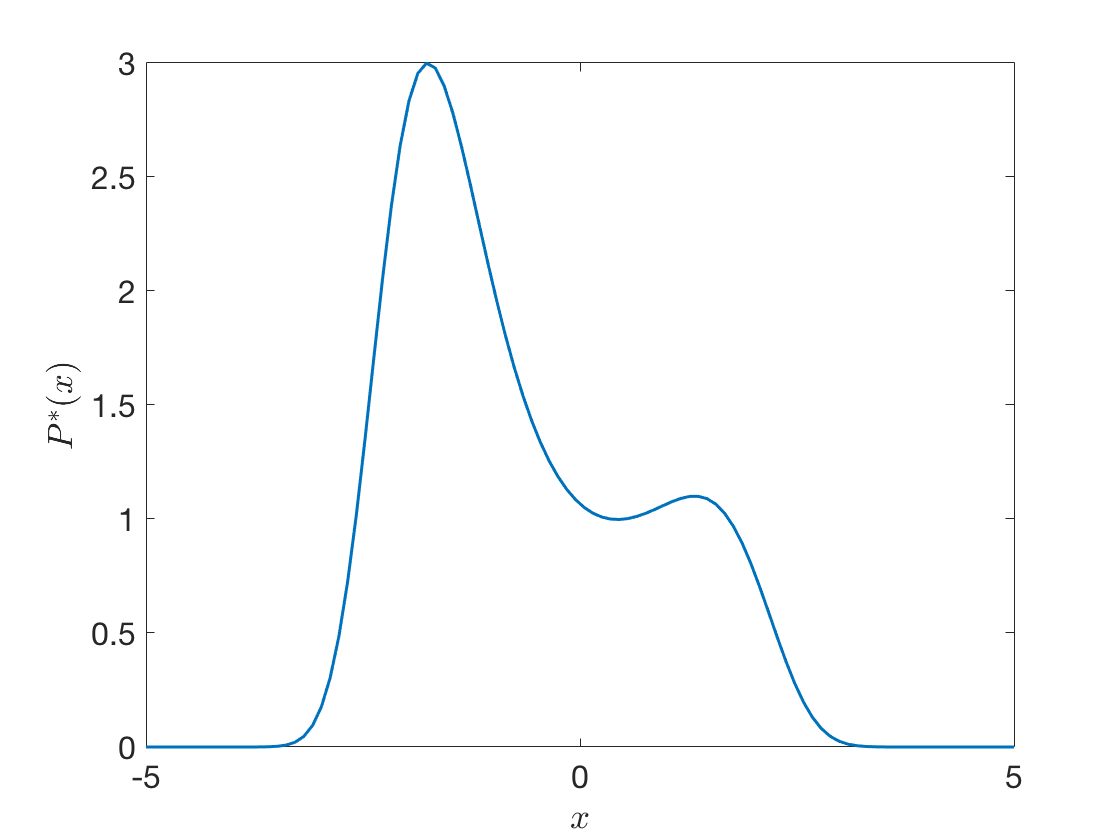

% define range of x values to evaluate function
x = linspace(-5, 5, 100);

% evaluate function P*(x)
Px = exp(0.4 * (x - 0.4).^2 - 0.08 * x.^4);

% plot function
plot(x, Px, 'Linewidth', 1.5)
% label axis
xlabel('$x$', 'Interpreter','latex')
ylabel('$P^*(x)$', 'Interpreter','latex')
% change font size
set(gca, 'FontSize', 16)

We can plot this fuction, but that doesn't mean that we can actually sample out of this odd looking multi-peak distribution. Maybe you are thinking that we could discretize the values of $x$ and use a finite set $\{x_i\}$instead. In this way we could evaluate the probability of each point $p^*_i \equiv P^*(x_i)$ and approximate the normalization constant as


$$Z \approx \sum_i p^*_i.$$


This will end up looking something like

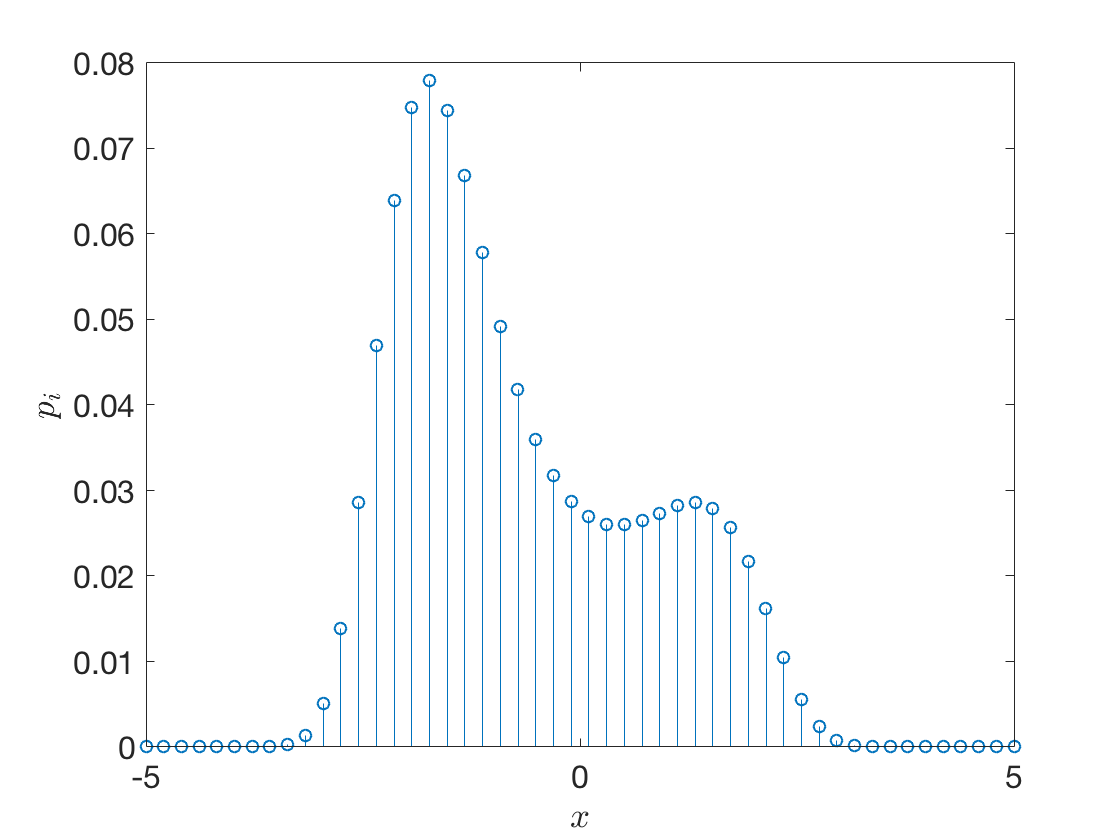

% define range of x values to evaluate function
x = linspace(-5, 5, 50);

% evaluate function P*(x)
Px = exp(0.4 * (x - 0.4).^2 - 0.08 * x.^4);

% Evaluate normalization
Z = sum(Px);

% Compute normalized distribution
Px = Px / Z;
% plot pmf
stem(x, Px, 'o')
% label axis
xlabel('$x$', 'Interpreter','latex')
ylabel('$p_i$', 'Interpreter','latex')
% change font size
set(gca, 'FontSize', 16)

But how does this discretization procedure scale with dimensionality of the space $N$? I am a big fan of David Mackay's argument of how poorly this procedure scales, so I'm just going to reproduce down below his exact argument:			

"*Let us concentrate on the initial cost of evaluating *$Z$*. To compute *$Z$* we have to visit every point in the space. In [the previous] figure there are 50 uniformly spaced points in one dimension. If our system had *$N$* dimensions, *$N = 1000$* say, then the corresponding number of points would be *$50^{1000}$*, an unimaginable number of evaluations of *$P^*$*. Even if each component *$x_n$* took only two discrete values, the number of evaluations of *$P^*$* would be *$2^{1000}$*, a number that is still horribly huge. If every electron in the universe (there are about *$2^{266}$* of them) were a *$1000$* gigahertz computer that could evaluate *$P^*$* for a trillion (*$2^{40}$*) states every second, and if we ran those *$2^{266}$* computers for a time equal to the age of the universe (*$2^{58}$* seconds), they would still only visit *$2^{364}$* states. We’d have to wait for more than *$2^{636} \approx 10^{190}$* universe ages to elapse before all *$2^{1000}$* states had been visited.*"

That simple example shows that without smart sampling one cannot tackle these problems. If you wonder what kind of model in biology would have in the order of 1000 parameters I can tell you that in modern Bayesian analysis this is not an outrageous scenario. For example, the Ising model first proposed by Erns Ising as a physical model of a simple magnet has found its way into biological problems that at first sight seem completely unrelated. The Ising model simply proposes that a set of magnetic spins on a grid interact with their neighbors and can be influenced by an external field. Each spin can take only two values (usually $x^{(i)} \in \{ +1, -1 \}$) and the probability of finding any configuration of a magnet with $N$ spins is of the form


$$P(\{ x^{(i)} \}_{i=1}^N) = {e^{- \sum_{ij} J_{ij} x^{(i)} x^{(j)} - h \sum_i x^{(i)}} \over \mathcal{Z}},$$


where the sum $\sum_{ij}$ is taken over all possible $(i, j)$ pairs, $J_{ij}$ is the coupling of the spins, $h$ is an external magnetic field and $\mathcal{Z}$ is the partition function. This model has been extensively use to represent neuronal networks where at each time point one can measure if a neuron is silent $x^{(i)} = -1$ or it fires $x^{(i)} = +1$, and very interesting insights into the structure of the brain can be learned. Also a generalization of this model where $x^{(i)}$ can take more than 2 values has been used to model the sequence of amino acids in evolving populations of viruses including influenza and HIV. The idea there is that the array $\{ x^{(i)} \}_{i=1}^N$ represents a specific amino acid sequence and we ask how likely is to find specific sequences in an evolving viral population. In these two cases one can get some data (electrophisiology for neurons and sequencing data for viruses) and from this we have to infer all interaction energies.

But the utilith of MCMC techniques is not limited to this type of model. For a non astronomical number of parameters, let's say > 2, it is already hard to divide a high-dimensional parameter space into discrete points to properly sample the posterior distribution.

# The idea behind Markov Chain Monte Carlo algorithms

You might still wonder what exactly are the Monte Carlo part and the Markov Chain part of an MCMC algorithm? A Monte Carlo method refers to any numerical algorithm that relies on random number sampling. The history of the weird name goes back to the Manhattan project where it were first implemented. At the time the inventors Stanislaw Ulman and Jon Von Newann needed a code name for the potentially game changing idea. They name it Monte Carlo after the famous Monaco casino for some personal reasons and the obvious relationship with randomness.

As for the Markov Chain part of the name that comes from the Russian mathematician Andrey Markov. Markov worked on this broad class of stochastic processes which consist of transitions between states on which the probability of each transition only depends on the current state of the system and not the entire history.

So if a Markov Chain transition from one state to another (from one proposed parameter value to another for example) depends on the current state how can such an algorithm give me a series of independent samples out of the target distribution $P(\mathbf{x})$? The answer resides on the fact that the samples need not to be independent. Instead we can design an algorithm that generates samples in the right proportion according to the distribution. That means that if for two points $\mathbf{x}$ and $\mathbf{x}'$ we have that $P(\mathbf{x}) > P(\mathbf{x}')$, then our algorithm should be more likely to sample $\mathbf{x}$ out of those two states.

The idea behind MCMC is then to take a **random walk** in the space where $\mathbf{x}$ lives such that the probability of the random walker landing at any point **is proportional to the probability **$P(\mathbf{x})$.

If we can set the rules such that this relationship is satisfied, then all we need to do is have the walker give a lot of steps and then use that Markov chain $\{\mathbf{x}^{(t)}\}_{i=0}^N$ as our sample to solve both problems 1 and 2!

Being a little more formal the statement that the probability of the walker landing at a point $\mathbf{x}^{(t+1)}$ is proportional to $P(\mathbf{x}^{(t+1)})$ may be stated as


$$P(\mathbf{x}^{(t+1)}) = \int d^N \mathbf{x}^{(t)} Q(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) P(\mathbf{x}^{(t)}),$$


where $Q(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)})$is the so-called transition kernel that defines the probability of transitioning from $\mathbf{x}^{(t)}$ to $\mathbf{x}^{(t + 1)}$. Note that I used superindex $(t)$ rather than $(i)$ to denote that these are not independent samples, but part of a Markov chain. All this nasty looking integral is saying is very simple: the probability of landing on $\mathbf{x}^{(t + 1)}$ is obtained summing (integrating for continous variables) over all possible jumps from any point $\mathbf{x}^{(t)}$ to the target point $\mathbf{x}^{(t + 1)}$.

The task is then to design a transition kernel $Q(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)})$ such that the generated chain is ergodic. What ergodic roughly means is that for a dynamical system (in this case our random walker dynamically walking in parameter space) to have the same behavior over time as if it was averaged over the space of all possible system states. In other words, an ergodic chain refers to a system in which if we were to have a random walker give many many steps over parameter space and we plotted its trajectory, or we instead had many many walkers stand imobile at different positions of this parameter space and also plotted their positions, we wouldn't be able to distinguish both plots.

The formal properties that an ergodic chain satisfies are:

- it is **aperiodic**. A chain that is periodic can only return to a given point in parameter space after $k$, $2k$, $\ldots$, steps, where $k$ is the period. An aperiodic chain is obviously not periodic.

- It is **irreducible**. This means that any point in parameter space can be accessed from any other point.

- It is **positive recurrent**. What this implies is that the walker should be able to come back o any point previously visited in a finite number of steps.

Let's now look at a famous algorithm that satisfies these conditions.

# The Metropolis-Hastings algorithm

The first implementation of an MCMC algorithm was the famous [Metropolis-Hastings algorithm](https://en.wikipedia.org/wiki/Metropolis–Hastings_algorithm). First proposed by Nicholas Metropolis in 1953 and then extended by W. K. Hastings in 1970 this algorithm helps us get around the difficulties presented in the previous section. Note: With an apology to Hastings from now on we will refer to the algorithm simply as the Metropolis algorithm since, as Mackay suggests, short names are important for relevant concepts.

## The idea behind the algorithm

The clever idea behind the Metropolis algorithm can be summarized as follows: Starting at some point in parameter space $\mathbf{x}^{(0)}$ a transition is propossed according to the transition kernel $Q(\mathbf{x}' \mid \mathbf{x}^{(0)})$ if this new proposed position "climbs up" the probability distribution $P^*(\mathbf{x})$, i.e. the value of $P^*(\mathbf{x'})$ is greater than $P^*(\mathbf{x}^{(0)})$ then the step is accepted and we set $\mathbf{x}^{(1)} = \mathbf{x}'$. If the proposed step does not climb up in probability, then a biased coin is flipped, where the bias depends on how much lower in probability the proposed point is, and based on this coin we decide if we accept the step, i.e. set $\mathbf{x}^{(1)} = \mathbf{x}'$ or we reject the step setting $\mathbf{x}^{(1)} = \mathbf{x}^{(0)}$. Then the process is repeated many more times. In the limit of repeating this many many times the Markov chain that we build $\{\mathbf{x}^{(t)}\}_{i=0}^N$ is an accurate sample out of the **normalized** distribution $P(\mathbf{x})$.

So far I have just preached black magic without showing why this procedure solves both problems. For that we need to formally list each step in the algorithm and then mathematically proof that the assertion that this procedure gives an ergodic chain is indeed true.

## The actual algorithm

Let's now list the steps that go into the algorithm.

**1. **Having the walker at some abritrary position $\mathbf{x}^{(t)}$, randomly choose a candidate position $\mathbf{x}'$using the proposal distribution $K(\mathbf{x}' \mid \mathbf{x}^{(t)})$. This distribtion $K(\mathbf{x}' \mid \mathbf{x}^{(t)})$ is **not** the same as the transition kernel $Q(\mathbf{x}' \mid \mathbf{x}^{(t)})$. This is just a random number generator to choose some position $\mathbf{x}'$ in the vincinity of $\mathbf{x}^{(t)}$.

**2. **Compute the **Metropolis ratio**, 


$$r = {P(\mathbf{x}') K(\mathbf{x}^{(t)} \mid \mathbf{x}') \over P(\mathbf{x}^{(t)}) K(\mathbf{x}' \mid \mathbf{x}^{(t)})}.$$


The logic behind this quantity will be explained in the next section when we show that this algorithm satisfies the conditions to generate a sample out of $P(\mathbf{x})$.

**3. **If $r \geq 1$, accept the step and set $\mathbf{x}^{(t+1)} = \mathbf{x}'$. Otherwise, accept the step with probability $r$. Note: If the step ends up being rejected is important to set $\mathbf{x}^{(t+1)} = \mathbf{x}^{(t)}$ rather than discarding the step.

The acceptance probability of the algorithm is then given by


$$\alpha(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) =
\min(1, r) =
\min \left( 1, {P(\mathbf{x}') K(\mathbf{x}^{(t)} \mid \mathbf{x}') \over P(\mathbf{x}^{(t)}) K(\mathbf{x}' \mid \mathbf{x}^{(t)})} \right).$$


As a consequence the transition Kernel $Q(\mathbf{x}^{(t + 1)} \mid \mathbf{x}^{(t)})$ is composed of the probability of choosing certain position times the probability of accepting such position, i.e.


$$Q(\mathbf{x}^{(t + 1)} \mid \mathbf{x}^{(t)}) \equiv K(\mathbf{x}^{(t + 1)} \mid \mathbf{x}^{(t)}) \cdot \alpha (\mathbf{x}^{(t + 1)} \mid \mathbf{x}^{(t)}).$$


## Detailed balance

Now we are left with the formal task of showing that this rather awkward algorithm generates a Markov chain with the desired properties. The way we will do this is by showing that the generated chain satisfies detailed balance. In the context of Markov processes detailed balance is a property that guarantees the existance of a stationary distribution $P(\mathbf{x})$. What this means is that if a Markov process satisfies detailed balance, there is a distribution $P(\mathbf{x})$ from which, in the limit of many steps in the chain, the steps are being sampled form this distribution. So if we can show that our algorithm satisfies such condition we will have shown that by letting the walker take many steps the generated chain can be used to solve our problems!

The condition to satisfy detail balance is that any transition from $\mathbf{x}^{(t)}$ to $\mathbf{x}^{(t+1)}$ should have the same probability as a transition from $\mathbf{x}^{(t+1)}$ to $\mathbf{x}^{(t)}$. This is mathematically expressed as


$$P(\mathbf{x}^{(t)}) Q(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) = 
P(\mathbf{x}^{(t+1)}) Q(\mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)}).$$


If the kernel $Q(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)})$ satisfies this property, the statement of detailed balance is equivalent to our initial requirement that the probability of landing at any point $\mathbf{x}^{(t+1)}$ should be proportional to $P(\mathbf{x}^{(t+1)})$. To show this statement about detailed balance is true we integrate the condition over all possible transitions


$$\int d^N \mathbf{x}^{(t)} P(\mathbf{x}^{(t)}) Q(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) = 
\int d^N \mathbf{x}^{(t)} P(\mathbf{x}^{(t+1)}) Q(\mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)}).$$


We now rewrite the equation as


$$\int d^N \mathbf{x}^{(t)} P(\mathbf{x}^{(t)}) Q(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) =
 P(\mathbf{x}^{(t+1)}) \int d^N \mathbf{x}^{(t)}Q(\mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)}).$$


Since the transition kernel is just a probability distribution, the integral on the right-hand side is equal to 1. Therefore we recover the condition we established for any transition


$$\int d^N \mathbf{x}^{(t)} P(\mathbf{x}^{(t)}) Q(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) = 
P(\mathbf{x}^{(t+1)}).$$


Having showed that a kernel that satisfies detailed balance also satisfies our condition that the propensity of landing at any point is proportional to the probability of such point let's show that the Metropolis algorithm satisfies detailed balance.

## Detailed balance in the Metropolis algorithm

Consider the joint distribution $P(\mathbf{x}^{(t+1)}, \mathbf{x}^{(t)})$. By the definition of conditional probability we have that


$$P(\mathbf{x}^{(t + 1)}, \mathbf{x}^{(t)}) = P(\mathbf{x}^{(t)}) \cdot Q( \mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}).$$


Given our definition of the transition kernel this can be written as


$$P(\mathbf{x}^{(t + 1)}, \mathbf{x}^{(t)}) = P(\mathbf{x}^{(t)}) \cdot \left[ K( \mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) \cdot \alpha( \mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) \right].$$


Using the acceptance probability definition we have


$$P(\mathbf{x}^{(t + 1)}, \mathbf{x}^{(t)}) = 
P(\mathbf{x}^{(t)}) \cdot
K( \mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) \cdot
\min \left( 1, {P(\mathbf{x}^{(t+1)}) K(\mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)}) \over P(\mathbf{x}^{(t)}) K(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)})} \right).$$


Now we use the property that multiplying the elements being compared in the $\min$ operator by a constant doesn't affect the outcome, i.e. $a \cdot \min(x, y) = \min(ax, ay)$. This allow us to rewrite the right hand side as


$$P(\mathbf{x}^{(t)}) \cdot
K( \mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) \cdot
\min \left( 1, {P(\mathbf{x}^{(t+1)}) K(\mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)}) \over P(\mathbf{x}^{(t)}) K(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)})} \right) = 
\min \left( P(\mathbf{x}^{(t)}) K(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}), {P(\mathbf{x}^{(t+1)}) K(\mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)})} \right).$$


Using the same property as in the previous step we now factorize out of the $\min$ operator ${P(\mathbf{x}^{(t+1)}) K(\mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)}$. This gives


$$\min \left( P(\mathbf{x}^{(t)}) K(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}), {P(\mathbf{x}^{(t+1)}) K(\mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)})} \right) = 
P(\mathbf{x}^{(t+1)}) \cdot K( \mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)}) \cdot \min \left( 1, {P(\mathbf{x}^{(t)}) K(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) \over P(\mathbf{x}^{(t+1)}) K(\mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)})} \right).$$


But we note that the right-hand side is exactly the definition of the transition kernel from $\mathbf{x}^{(t+1)}$ to $\mathbf{x}^{(t)}$, i.e.


$$P(\mathbf{x}^{(t+1)}) \cdot K( \mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)}) \cdot \min \left( 1, {P(\mathbf{x}^{(t)}) K(\mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) \over P(\mathbf{x}^{(t+1)}) K(\mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)})} \right) = 
P(\mathbf{x}^{(t+1)}) \cdot Q( \mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)}).$$


So we just showed that our definition of the transition kernel satisfies the condition


$$P(\mathbf{x}^{(t)}) \cdot Q( \mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)}) = P(\mathbf{x}^{(t+1)}) \cdot Q( \mathbf{x}^{(t)} \mid \mathbf{x}^{(t+1)}),$$


i.e. satisfies detailed balance!

Let's quickly recapitulate what we have done so far. We first proposed a transition kernel $Q( \mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)})$ made out of two probabilities, the proposal distribution $K( \mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)})$ and the acceptance distribution $\alpha( \mathbf{x}^{(t+1)} \mid \mathbf{x}^{(t)})$. We then showed that if our proposed kernel satisfies detailed balance, then applying this kernel would allow us to effectively sample our desired distribution $P(\mathbf{x})$. We finally showed that indeed the kernely that we proposed was not a random choice, but an intelligently designed kernel that satisfies detailed balance. With all these proofs in place we can finally code our own Metropolis algorithm understanding the reason behind each step.

# Coding your own Metropolis sampler

It is time to finally implement our own metropolis sampler. For this we have written (or will write in class) two functions:

- `metropolistStep`. This function given a log posterior function and the current position of the walker defines whether or not a proposed step sampled out of a Gaussian distribution should be accepted.

- `metropolisSample`. This function uses the previous function and repeats the steps many times, building the Markov chain that we will use as our sample out of $P(\mathbf{x})$. This function implements something called a burn-in. That is initializing a walker and letting it walk for a bit without tracking its position to then use the last position of this walk as the initial position for building the Markov chain. This serves as a way to let the walker find a good spot in parameter space from which to start. Otherwise if the walker is initialize in a useless part of parameter space a lot of the recorded steps would be "wasted" in trying to find a relevant part of the probability density.

Having gone thourgh the logic of these functions let's now implement them. We will use some of the code developed in the previous tutorial to get directly to the implementation of the sampler. To see the details of the question we are trying to answer please take a look to the first tutorial on the bootcamp website.

The first thing we need to do is import the data into the MATLAB environment.

% Read the data frame containing the experimental measurements
df = readtable('Garcia2011_AbsoluteSinglelacZ_wFC.csv');

% Display 3 specific colums of the data set
df(1:5,{'operator', 'repressors', 'fold_change'})

ans = 5×3 table
    operator    repressors    fold_change
    ________    __________    ___________

     'Oid'         610        0.00022109 
     'O1'          610         0.0012936 
     'O2'          610          0.006133 
     'Oid'          11         0.0066914 
     'O1'           11          0.037764 


Again just as in the previous tutorial we will focus on the data coming from the O2 operator. So let's use what we learned about boolean indexing to extract the relevant data.

% Select rows that have operator O2 and a positive number of repressors (removing ∆lacI strain)
O2Rows = df.operator == "O2" & df.repressors > 0;

% Use the boolean array to extract the data for O2 from the general data frame.
% We will extract only the columns we care about to keep it simple.
dfO2 = df(O2Rows, {'operator', 'repressors', 'fold_change'});

% Display the first 5 rows
dfO2(1:5,:)

ans = 5×3 table
    operator    repressors    fold_change
    ________    __________    ___________

      'O2'         610          0.006133 
      'O2'          11           0.17904 
      'O2'         610          0.007307 
      'O2'          11            0.1575 
      'O2'         610         0.0047205 


It doesn't hurt to look at the raw data to remind us what we are dealing with. So let's plot the gene expression fold-change as a function of the repressor copy number.

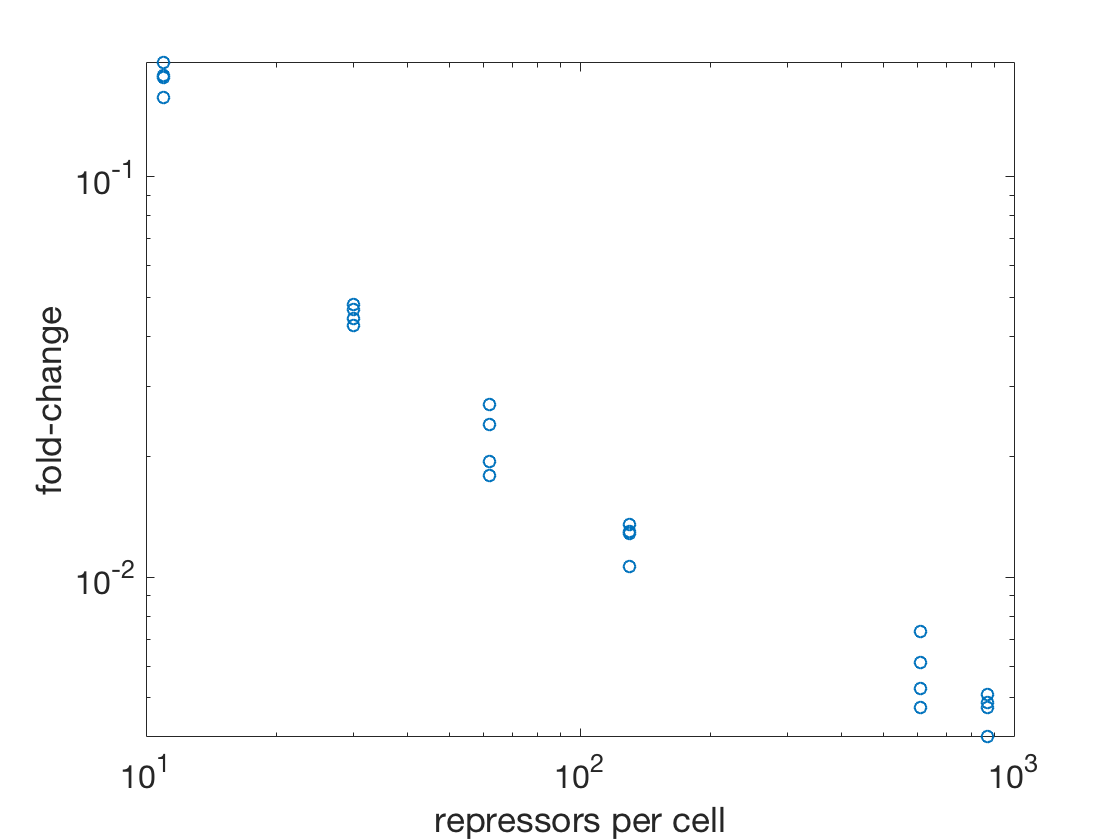

% Plot repressor vs fold-change on a log-log plot.
loglog(dfO2.repressors, dfO2.fold_change, 'o')

% Label axis
xlabel('repressors per cell')
ylabel('fold-change')

% Change the font size
set(gca, 'FontSize', 16)

## Defining anonymous function to feed into the `metropolisSample` function.

The `metropolisSample` function we defined takes as an argument a `logPost` function that is used to compute the log posterior probability. In the previous tutorial we wrote down a function `logPosterior.m` where we compute the desired log posterior probability. The problem with this function implementation is that it takes as extra arguments the actual data used to evaluate the function. This cannot be fed into our `metropolisSample` function, so just as we did when we computed the hessian in the previous tutorial we will defina an anonymous function that uses our `logPosterior` script but fixes the data into it.

%Define anonymous function to compute -logPosterior of the O2 data
mcmcLogPosteriorO2 = @(epsilonR) logPosterior(dfO2.fold_change, dfO2.repressors, epsilonR);

% Test the function feeding a single parameter
mcmcLogPosteriorO2(-13.7)

ans = 58.6459

## Run MCMC

Having defined the log posterior distribution we can finally test our Metropolis algorithm!

Let's first define all the necessary inputs for the `metropolisSample` function.

% Walker initial position 
x0 = 0;
% Standard deviation for the Gaussian proposal distribution K(x(t+1) | x(t))
 sigma = 0.5; % kBT
% number of burn-in steps
nBurn = 2000;
% number of steps for real MCMC
nSteps = 20000;

Now we are ready to run the MCMC. Let's not delay the big moment and run it now.

% run MCMC using our home-coded Metropolis algorithm
mcmcChain = metropolisSample(mcmcLogPosteriorO2, x0, sigma, nBurn, nSteps);

## Analyzing the results

That ran relatively fast. Obviously the time it takes to run scales with the number of steps, the number of parameters and, with other MCMC implementations, the number of walkers running in parallel.

Now we can use our mcmcChain to look at the posterior distribution for our desired parameter. Let's display a histogram of all of the steps that the walker took. After all these can be treated as samples out of $P(\Delta \varepsilon_r \mid D)$.

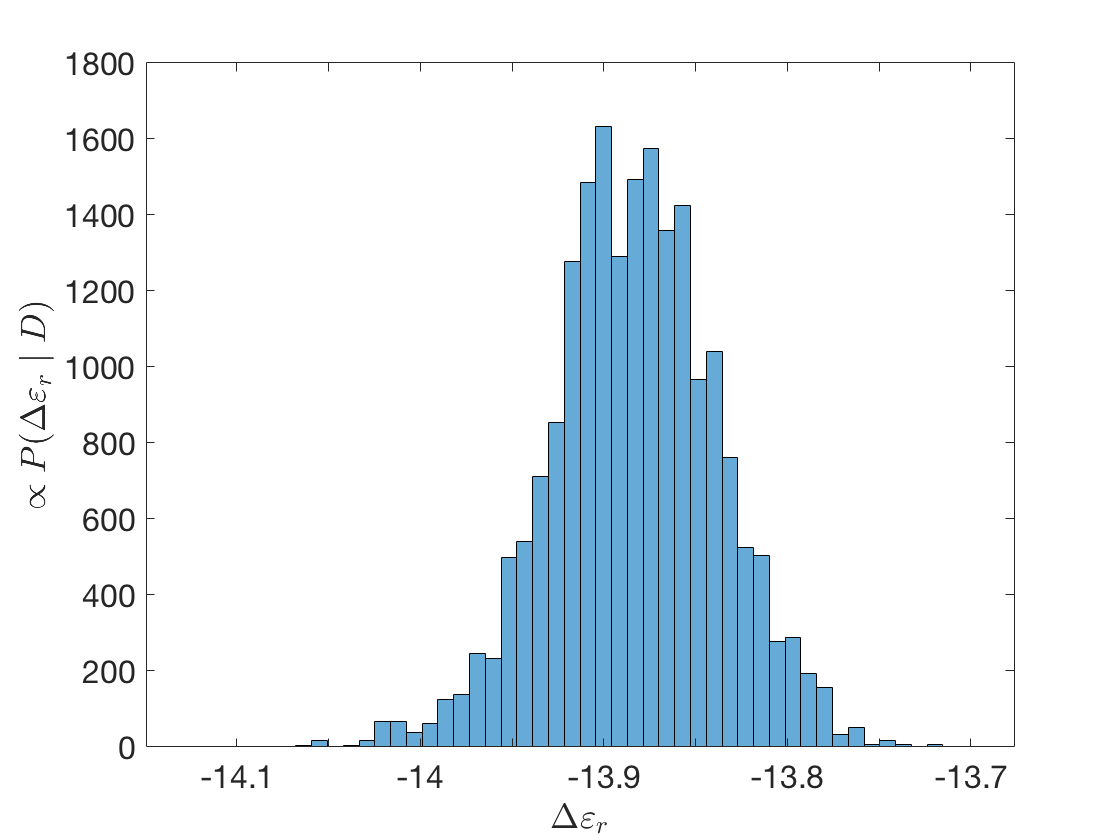

% Plot histogram of walker positions
histogram(mcmcChain(:, 1), 50)

% label axis
xlabel('$\Delta\varepsilon_r$', 'Interpreter','latex')
ylabel('$\propto P(\Delta\varepsilon_r \mid D)$', 'Interpreter','latex')

% Change the font size
set(gca, 'FontSize', 16)

The distribution seems to be centered at the same values as what we obtained with optimization in the previous tutorial. So both methods agree that the binding energy for the O2 operator is around -13.9 $k_BT$. But how do we actually find the MAP? We conveniently made our function `metropolisSample` return the non-normalized log posterior probability for a reason. All we need to do is find the value for which this log posterior is maximum and we will have found the **Max**imum Aposteriori Parameter.

% Locate the index of the walker position that gave the larges logPosterior probability
[value, idx] = max(mcmcChain(:, 2));

% Find the energy value corresponding to this index
poptO2 = mcmcChain(idx, 1)

poptO2 = -13.8825

As expected we obtained a value very close to -13.9 $k_BT$.

# Conclusion

In this tutorial we went through the logic of why MCMC algorithms are necessary. We then derived the famous Metropolis-Hastings algorithm and mathematically showed that  it should converge to our desired posterior probability. We then implemented the algorithm with basic MATLAB functions and used it to analyze the posterior distribution of the repressor-DNA binding energy.